# Resample Data

This code loads and plots electrical conductivity data. 

concentration=[0 142 610 1170 2035 2297 2665 3264 3568 4349 5948]

concentration =            0         142         610        1170        2035        2297        2665        3264        3568        4349        5948


conductivity=[42 592 1040 1605 2170 2756 3137 4030 4341 4878 5115]

conductivity =           42         592        1040        1605        2170        2756        3137        4030        4341        4878        5115


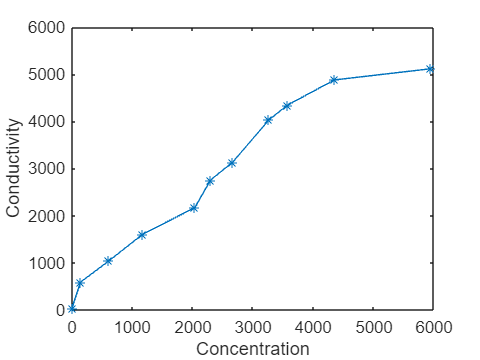

plot(concentration,conductivity,"*-");
xlabel("Concentration")
ylabel("Conductivity")

## Task 1

One useful application of interpolation is to find an even sampling of data. 

In this activity, you will work with a different type of electrical data.

Adding salt to water will affect the electrical conductivity of the water. `conductivity` is a vector containing the conductivity of water at each salt concentration in `concentration`.

As seen in the plot, the concentration values are not at even increments.  You can resample your data by creating a vector of evenly spaced values  and using the `interp1` function.

Task

The `concentration` vector contains values between about 0 and 5000. 

Create a vector `xNew` of 11 evenly spaced values between 0 and 5000 using the `linspace` function.

xNew=linspace(0,5000,11)

xNew =            0         500        1000        1500        2000        2500        3000        3500        4000        4500        5000


## Task 2

Recall the syntax for the `interp1` function:

`yi` `=` `interp1``(``x``,``y``,``xi``)`

If the input `xi` is a vector, then `yi` will be a vector of the interpolated values at each point. 

Task

Find the interpolated value at each point in `xNew` using the `interp1` function. Assign the output to the variable `yNew`.

The known data is in the vectors `concentration` and `conductivity`.

yNew=interp1(concentration,conductivity,xNew)

yNew = 1.0e+03 *

    0.0420    0.9347    1.4335    1.8205    2.1471    2.9662    3.6364    4.2714    4.6380    4.9004    4.9745


## Task 3

Plot the interpolated conductivity values `yNew` as a function of concentration values `xNew` together with the original conductivity data using the `hold` `on` command. 

Use a circle marker to plot the points and remember to use the `hold` `off` command when finished plotting.

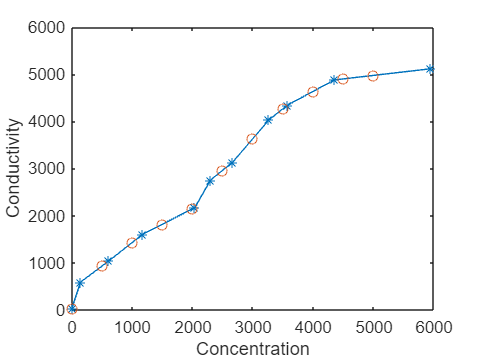

hold on
plot(xNew,yNew,"o")
hold off

## Further Practice

You have created an evenly spaced linear interpolation of the original  data. Notice that each interpolated point is exactly on the line segment connecting consecutive points.

In the next lesson, you will learn about different types of interpolation methods.